DISCLAIMER:  Software and data is for education and not for medical or commercial use. They are provided as-is, and any express or implied warranties, including but not limited to implied warranties of  merchantability and fitness for a particular purpose, are disclaimed. Use it at your own discretion.

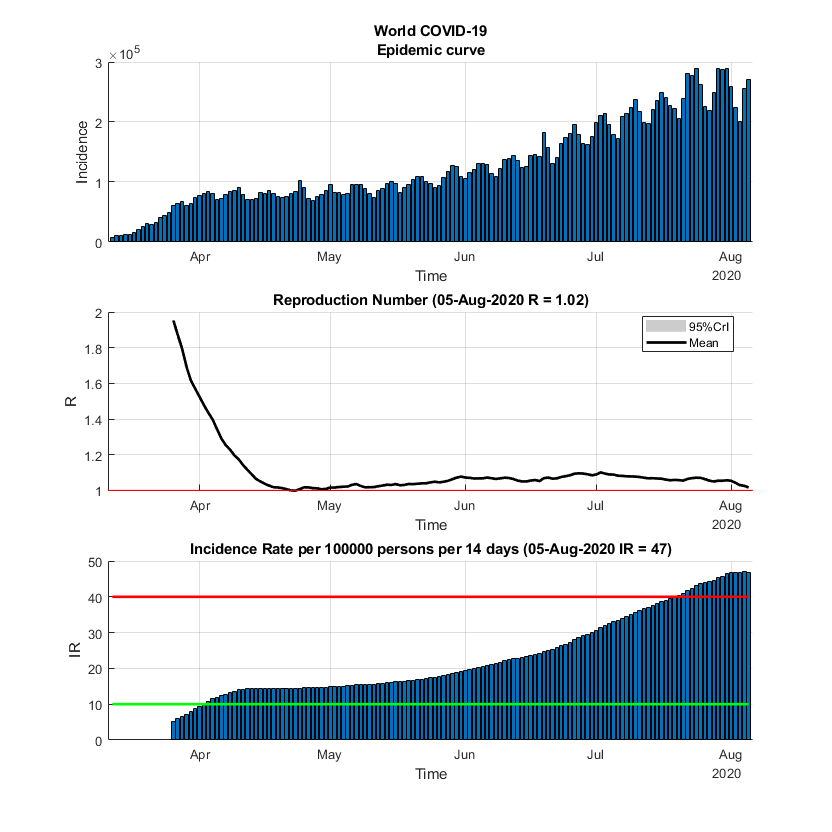

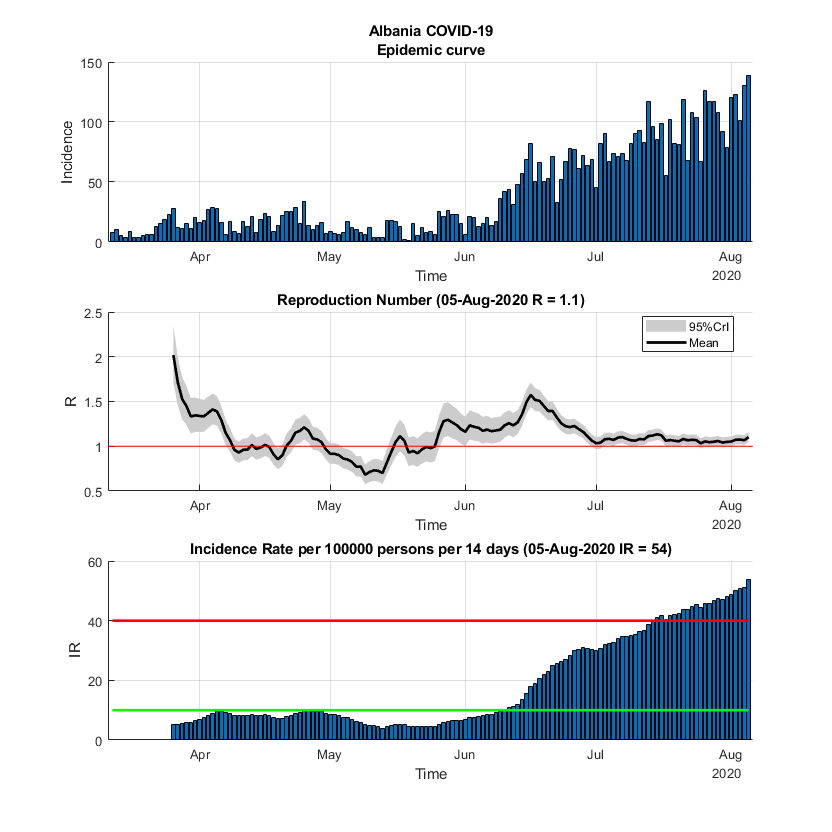

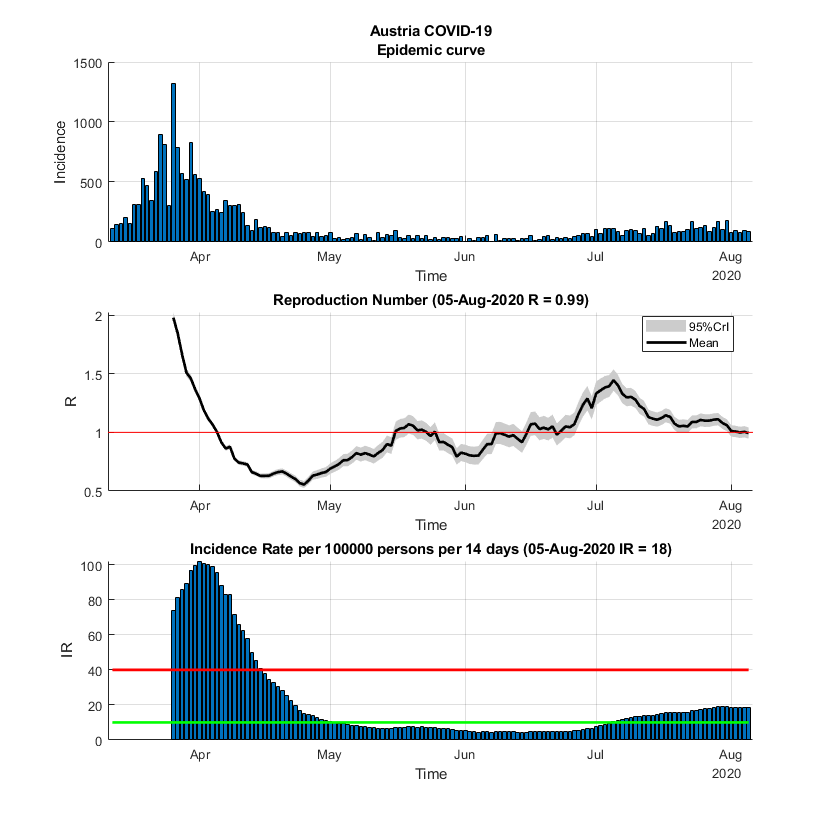

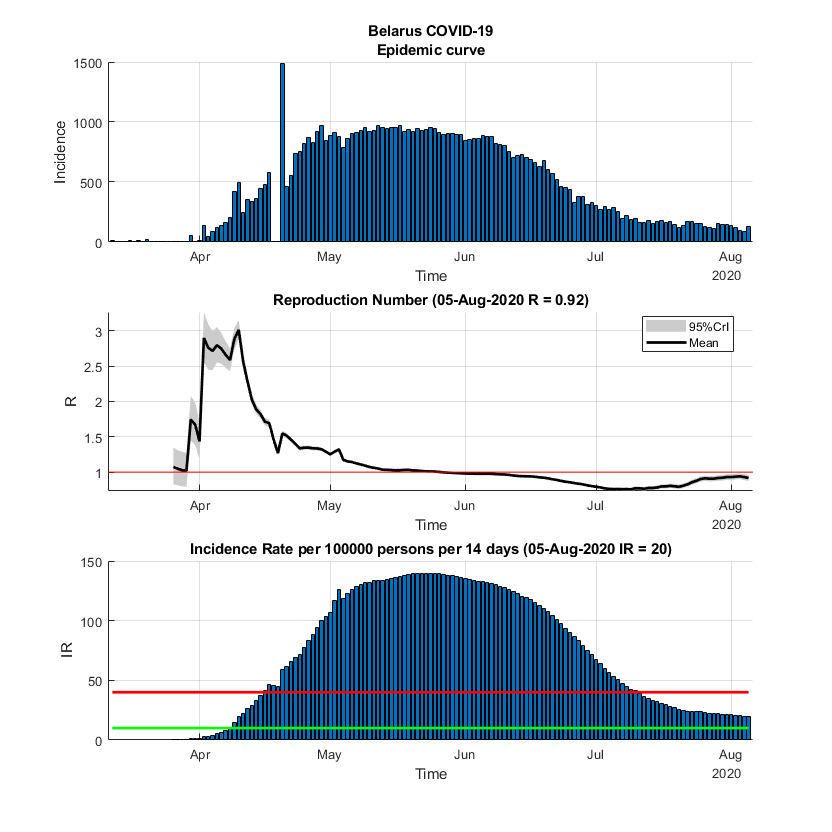

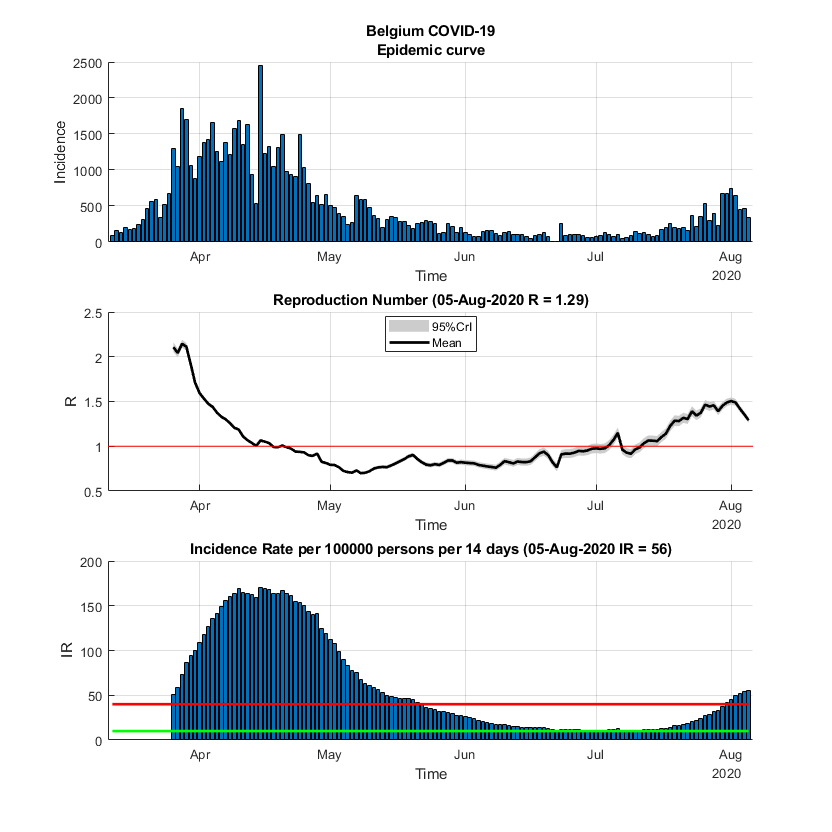

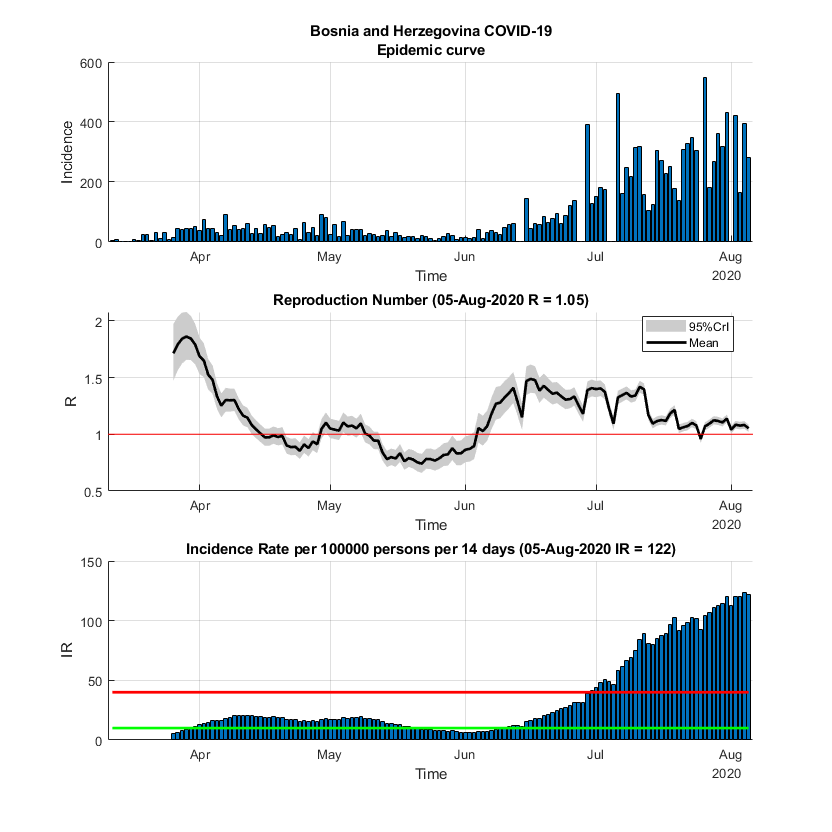

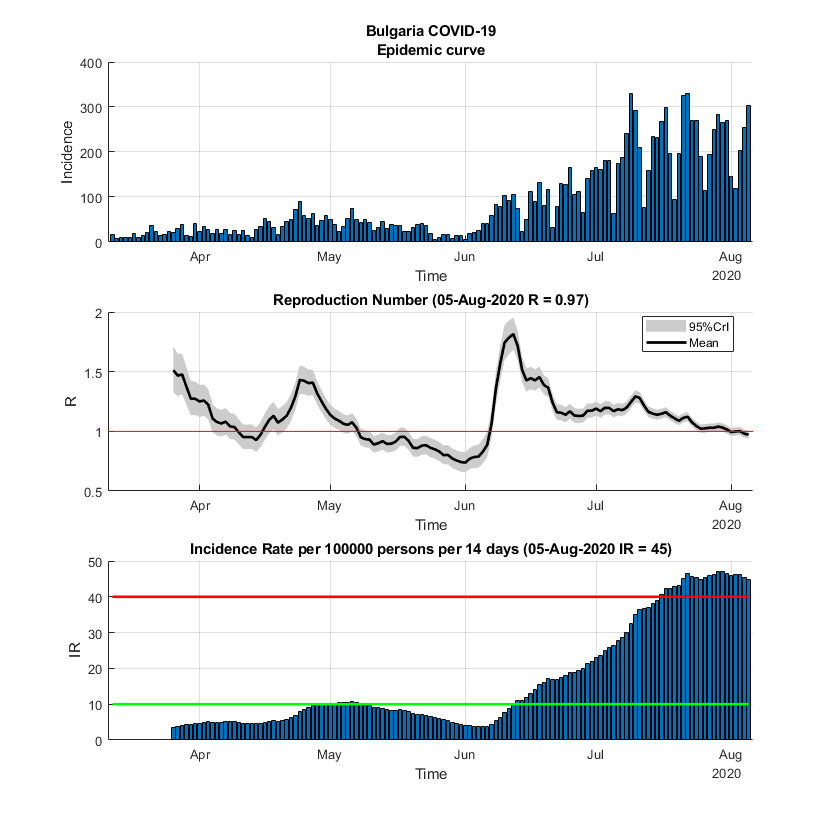

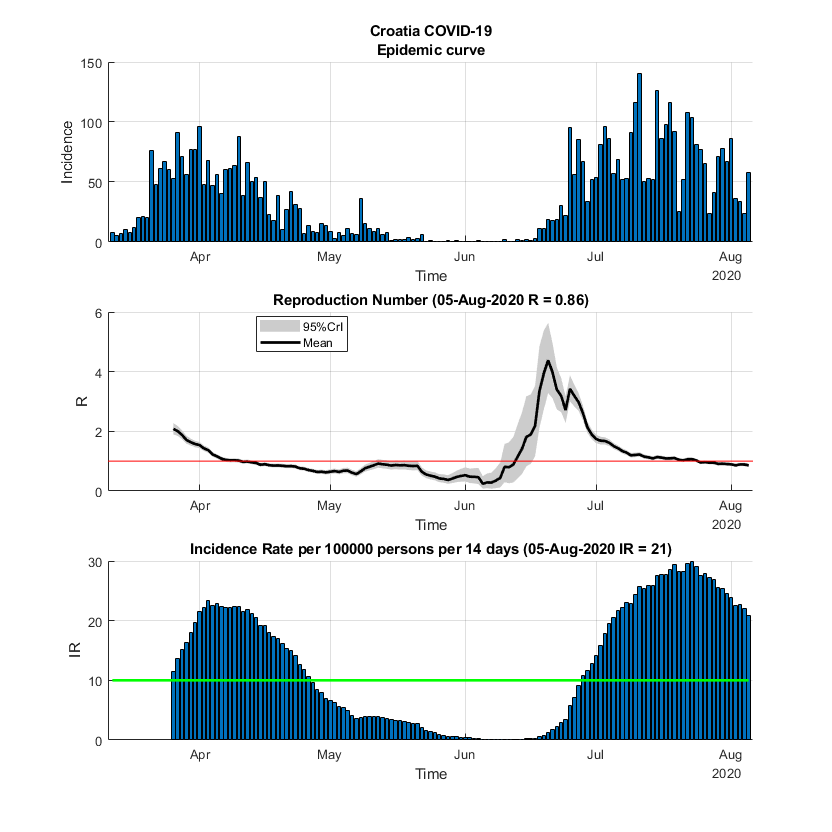

% estimate average R for different countries
addpath(genpath('mEpiEstim'))
addpath('data')
% Data ======================
start_date = [2020,3,12];  % use [] for complet data set
span = 14;  % 7 = weekly 14 = biweekly
mean_si = 4.7;
std_si = 2.9;
%============================
names = getCountryNames();
for n = 1:length(names)
    country = names(n);
    country = strrep(country,' ','_');
    country = strrep(country,'-','_');
    incid = importData(country,start_date);
    if isempty(incid)
        fprintf('No data for %s.\n',country)
        continue
    end
    T = length(incid.I);
    t_start = 2:T-span+1; % starting at 2 as conditional on the past observations
    t_end = t_start + span-1;
    res = estimate_R(incid, ...
        'parametric_si',...
        'config', make_config(...
        't_start',t_start,'t_end',t_end,...
        'mean_si', mean_si,...
        'std_si', std_si));
    plot(res,'what',['incid','R','IR'],'title',sprintf('%s COVID-19',incid.name),...
        'opt_I',options(...
        'plot_type','bar'),...
        'opt_IR',options('plot_type','bar'))
end

function names = getCountryNames()
names = [
    "World"
    %"Afghanistan"
    "Albania"
    %"Algeria"
    %"Andorra"
    %"Angola"
    %"Antigua-and-Barbuda"
    %"Argentina"
    %"Aruba"
    %"Armenia"
    %"Australia"
    "Austria"
    %"Azerbaijan"
    %"Bahamas"
    %"Bahrain"
    %"Bangladesh"
    %"Barbados"
    "Belarus"
    "Belgium"
    %"Belize"
    %"Benin"
    %"Bermuda"
    %"Bhutan"
    %"Bolivia"
    "Bosnia_and_Herzegovina"
    %"Brazil"
    %"Brunei-Darussalam"
    "Bulgaria"
    %"Burkina-Faso"
    %"Cambodia"
    %"Cameroon"
    %"Canada"
    %"Cabo-Verde"
    %"Cayman-Islands"
    %"Central-African-Republic"
    %"Chad"
    %"Chile"
    %"China"
    %"Colombia"
    %"Congo"
    %"Costa-Rica"
    "Croatia"
    %"Cuba"
    "Cyprus"
    "Czech-republic"
    %"Congo"
    "Denmark"
    %"Djibouti"
    %"Dominica"
    %"Dominican-Republic"
    %"Ecuador"
    %"Egypt"
    %"El-Salvador"
    %"Equatorial-Guinea"
    %"Eritrea"
    "Estonia"
    %"Ethiopia"
    %"Faeroe-Islands"
    %"Fiji"
    "Finland"
    "France"
    %"French-Polynesia"
    %"Gabon"
    %"Gambia"
    %"Georgia"
    "Germany"
    %"Ghana"
    "Gibraltar"
    "Greece"
    %"Greenland"
    %"Grenada"
    %"Guatemala"
    %"Guinea"
    %"Guyana"
    %"Haiti"
    %"Honduras"
    "Hungary"
    "Iceland"
    %"India"
    %"Indonesia"
    %"Iran"
    %"Iraq"
    "Ireland"
    %"Isle-of-Man"
    "Israel"
    "Italy"
    %"Ivory-Coast"
    %"Jamaica"
    %"Japan"
    %"Jordan"
    %"Kazakhstan"
    %"Kenya"
    %"Kuwait"
    %"Kyrgyzstan"
    %"Laos"
    "Latvia"
    %"Lebanon"
    %"Liberia"
    %"Libya"
    "Liechtenstein"
    "Lithuania"
    "Luxembourg"
    "Macedonia"
    %"Madagascar"
    %"Malaysia"
    %"Maldives"
    "Malta"
    %"Mauritania"
    %"Mauritius"
    %"Mexico"
    "Moldova"
    "Monaco"
    %"Mongolia"
    "Montenegro"
    %"Montserrat"
    %"Morocco"
    %"Mozambique"
    %"Myanmar"
    %"Namibia"
    %"Nepal"
    "Netherlands"
    %"New-Caledonia"
    %"New-Zealand"
    %"Nicaragua"
    %"Niger"
    %"Nigeria"
    "Norway"
    %"Oman"
    %"Pakistan"
    %"State-of-Palestine"
    %"Panama"
    %"Papua-New-Guinea"
    %"Paraguay"
    %"Peru"
    %"Philippines"
    "Poland"
    "Portugal"
    %"Qatar"
    "Romania"
    "Russia"
    %"Rwanda"
    %"Saint-Lucia"
    %"San-Marino"
    %"Saudi-Arabia"
    %"Senegal"
    "Serbia"
    %"Seychelles"
    %"Singapore"
    "Slovakia"
    "Slovenia"
    %"Somalia"
    %"South-Africa"
    %"South-Korea"
    "Spain"
    %"Sri-Lanka"
    %"Sudan"
    %"Suriname"
    %"Swaziland"
    "Sweden"
    "Switzerland"
    %"Syria"
    %"Taiwan"
    %"Tanzania"
    %"Thailand"
    %"Timor-Leste"
    %"Togo"
    %"Trinidad-and-Tobago"
    %"Tunisia"
    "Turkey"
    %"Uganda"
    "Ukraine"
    %"United-Arab-Emirates"
    "UK"
    "US"
    %"USA/Florida"
    %"USA/Texas"
    %"Uruguay"
    %"Uzbekistan"
    %"Holy-See"
    %"Venezuela"
    %"Viet-nam"
    %"Zambia"
    %"Zimbabwe"
    ];
end